clc; clear all; close all;

% Define symbolic variables
syms h(t) K h0 A_output A_tank g

% Set up the differential equation
diffeq = diff(h,t) == -K*sqrt(h)

$$diffeq(t) = \frac{\partial }{\partial t}h\left(t\right)=-K\,\sqrt{h\left(t\right)}$$


% Solve the differential equation without initial condition
hSol(t) = dsolve(diffeq)

$$hSol(t) = \left(\begin{array}{c} {\left(C_{1}-\frac{K\,t}{2}\right)}^{2}\\ 0 \end{array}\right)$$


% Solve the differential equation with initial condition
cond = h(0) == h0;
hSol2(t) = dsolve(diffeq, cond);
hSol2(t) = subs(hSol2, K, A_output/A_tank * sqrt(2*g))

$$hSol2(t) = \left(\begin{array}{c} {\left(\sqrt{h_{0}}+\frac{\sqrt{2}\,A_{\mathrm{output}}\,\sqrt{g}\,t}{2\,A_{\mathrm{tank}}}\right)}^{2}\\ {\left(\sqrt{h_{0}}-\frac{\sqrt{2}\,A_{\mathrm{output}}\,\sqrt{g}\,t}{2\,A_{\mathrm{tank}}}\right)}^{2} \end{array}\right)$$


% Substitute symbolic variable with numerical value
D = 0.04;
d = 0.004;
hSol2(t) = subs(hSol2, A_output, pi/4*d^2);
hSol2(t) = subs(hSol2, A_tank, pi/4*D^2);
hSol2(t) = subs(hSol2, g, 10);
hSol2(t) = subs(hSol2, h0, 0.1);

% Present solution of differential equation with numerical constants
hSol2;

% Select the correct solution (so that the time will be positive)
h =sym2cell(hSol2(t))

h = 2×1 cell array
    {[(10^(1/2)/10 + (4636172453169358125*2^(1/2)*10^(1/2)*t)/(295147905179352825856*pi))^2]}
    {[(10^(1/2)/10 - (4636172453169358125*2^(1/2)*10^(1/2)*t)/(295147905179352825856*pi))^2]}



% Set the height to zero, and solve equation for the time variable
eq = 0 == cell2sym(h(2))

$$eq = 0={\left(\frac{\sqrt{10}}{10}-\frac{4636172453169358125\,\sqrt{2}\,\sqrt{10}\,t}{295147905179352825856\,\pi }\right)}^{2}$$

t = vpa(solve(eq,t))

$$t = \left(\begin{array}{c} 14.142135623730951995293964360524\\ 14.142135623730951995293964360524 \end{array}\right)$$


% Plotting of the resulting equation (unrealistic)
dt = 10^-4;
t = 0;
i = 1;
wasZero = false;
while(t <= 28.3)
    height = (sqrt(10)/10 - (4636172453169358125*sqrt(2)*sqrt(10)*t)/(295147905179352825856*pi))^2;
    
    h_plot_analytical(i) = height;
    t_plot(i) = t;
    
    t = t + dt;
    i = i + 1;
end

fig = figure;
plot(t_plot,h_plot_analytical, 'r', 'LineWidth', 2)
title("Analytical Tank Problem Unrealistic", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Height [m]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("h(t)", 'Interpreter', 'latex')
ylim([-0.01 0.1])
xlim([0 28.3])
grid
filename = "analytical_solution_tank_problem_unrealistic.eps"

filename = "analytical_solution_tank_problem_unrealistic.eps"

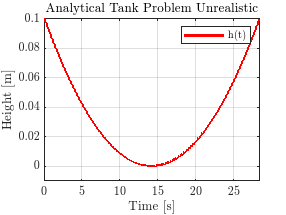

saveas(fig,filename, 'epsc')


% Plotting of the resulting equation (realistic)
clear t_plot
dt = 10^-4;
t = 0;
i = 1;
wasZero = false;
while(t <= 16)
    height = (sqrt(10)/10 - (4636172453169358125*sqrt(2)*sqrt(10)*t)/(295147905179352825856*pi))^2;
    if(height >= 0.0001)
        h_plot_analytical_real(i) = height;
    else
        wasZero = true;
        t_save = t;
        h_plot_analytical_real(i) = 0;
    end

    if(wasZero)
        h_plot_analytical_real(i) = 0;
    end
t_plot(i) = t;

t = t + dt;
i = i + 1;
end

fig = figure;
plot(t_plot,h_plot_analytical_real, 'r', 'LineWidth', 2)
title("Analytical Tank Problem", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Height [m]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("h(t)", 'Interpreter', 'latex')
grid
filename = "analytical_solution_tank_problem.eps"

filename = "analytical_solution_tank_problem.eps"

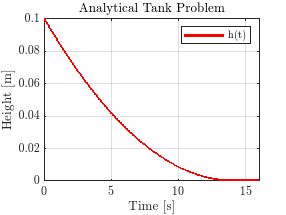

saveas(fig,filename, 'epsc')


[height, idx] = min(h_plot_analytical_real);
time_at_zero = t_plot(idx(1))

time_at_zero =           13.6949999999814



ddiffeq = diff(diffeq)

$$ddiffeq(t) = \frac{\partial^{2}}{\partial t^{2}}h\left(t\right)=-\frac{K\,\frac{\partial }{\partial t}h\left(t\right)}{2\,\sqrt{h\left(t\right)}}$$

## Numerical approach

simTime = 16; % s
t = 0; % Start time
dt = 10^-4;
idx = 1; % Index for logging

A_output = pi/4*d^2;
A_tank = pi/4*D^2;
g = 10;
h = 0.1;
while t < simTime
    % Calculations
    v = sqrt(2*g*h);
    Q = v*A_output;
    hDot = -Q/A_tank;

    % Save results for plotting
    t_plot_numerical(idx) = t;
    h_plot_numerical(idx) = h;
    h_DotPlot(idx) = hDot;

    % Time integrate and update time, index variables
    h = h+hDot*dt;          % Height
    t = t+dt;               % Current time
    idx = idx+1;            % Index for logging
end

fig = figure;
plot(t_plot_numerical,h_plot_numerical, 'k', 'LineWidth', 2)

title("Numerical Tank Problem", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Height [m]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("h(t)", 'Interpreter', 'latex')
grid
filename = "numerical_solution_tank_problem.eps"

filename = "numerical_solution_tank_problem.eps"

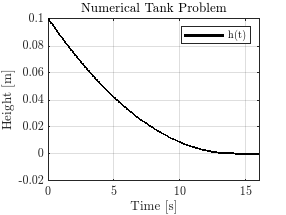

saveas(fig,filename, 'epsc')

hold off

fig = figure;
plot(t_plot_numerical,h_DotPlot, 'b', 'LineWidth', 2)

filename = "numerical_dot_solution_tank_problem.eps"

filename = "numerical_dot_solution_tank_problem.eps"

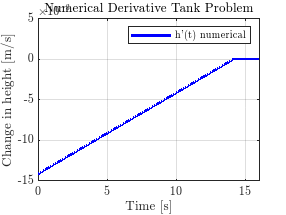

title("Numerical Derivative Tank Problem", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Change in height [m/s]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("h'(t) numerical", 'Interpreter', 'latex')
grid on
ylim([-0.015 0.005])
saveas(fig,filename, 'epsc')


fig = figure;
hold off
plot(t_plot_numerical,h_plot_analytical_real, 'r', 'LineWidth', 2)
hold on
plot(t_plot_numerical,h_plot_numerical, 'ko', 'MarkerIndices', 1:50000:length(h_plot_numerical),'LineWidth',2)

title("Analytical vs. Numerical Tank Problem", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Height [m]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("h(t) analytical", "h(t) numerical", 'Interpreter', 'latex')
grid on
filename = "analytical_vs_numerical_solution_tank_problem.eps"

filename = "analytical_vs_numerical_solution_tank_problem.eps"

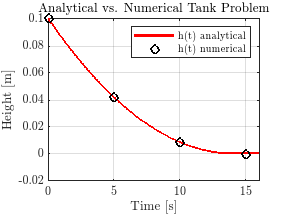

saveas(fig,filename, 'epsc')

hold off

fig = figure;
% Data from video
t = [0 0.744 1.602 2.525 3.514 4.537 5.658 6.911 8.593 10.437 12.2 14.6 16];
h = [0.1 0.09 0.08 0.07 0.06 0.05 0.04 0.03 0.02 0.01 0.005 0.001 0];

% Arguments: t list, h list, polynomial degree
p = polyfit(t,h, 2);

% Make a new list with points on the polynomial line based on the time
% values
polynomial_line = polyval(p, t);

% Plot result
plot(t,polynomial_line, 'r', 'LineWidth', 2)
hold on
plot(t,h, 'bo', 'LineWidth', 2)
plot(t_plot_numerical,h_plot_analytical_real, 'k', 'LineWidth', 2)
title("Polynomial line vs. Analytical Tank Problem", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Height [m]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("Polynomial line", "Data points", "h(t) analytical", 'Interpreter', 'latex')
grid on
filename = "polynomial_vs_analytical_solution_tank_problem.eps"

filename = "polynomial_vs_analytical_solution_tank_problem.eps"

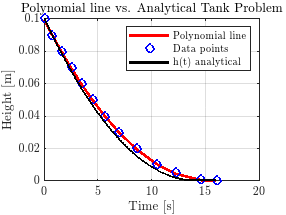

saveas(fig,filename, 'epsc')


syms t g A1 A2 h0

diff((sqrt(h0)-(sqrt(2*g)*A1/A2)/2*t)^2)

$$ans = -\frac{\sqrt{2}\,A_{1}\,\sqrt{g}\,\left(\sqrt{h_{0}}-\frac{\sqrt{2}\,A_{1}\,\sqrt{g}\,t}{2\,A_{2}}\right)}{A_{2}}$$